%---- Information ---
clc, clear , close all
digits(15)

syms x f(x)
f(x)= 2*x+3*exp(x);
exact= f(1);

y0 = 3 ;
x0 = 0 ;

hValue=[0.2, 0.1, 0.05, 0.025, 0.02, 0.0125, 0.01, 0.00625, 0.003125, 0.002, 0.001];
hNum = size(hValue,2);

eulerAns= zeros(1,hNum);
rungeKutta2Ans= zeros(1,hNum);
rungeKutta4Ans= zeros(1,hNum);

%---- Part A - Euler Method ---

for i=1:hNum
    eulerAns(1,i) = euler(x0,y0,hValue(1,i));
end

error1= vpa(abs(eulerAns-exact))

$$error1 = \left(\begin{array}{ccccccccccc} 0.689885485377136 & 0.373618105077135 & 0.194952369943875 & 0.0996539702072177 & 0.0800813981563202 & 0.050390663117124 & 0.0404039971125574 & 0.0253387564538059 & 0.0127055542541043 & 0.00813992342195745 & 0.00407368866945922 \end{array}\right)$$

eulerAns= vpa(eulerAns)

$$eulerAns = \left(\begin{array}{ccccccccccc} 9.46496 & 9.7812273803 & 9.95989311543326 & 10.0551915151699 & 10.0747640872208 & 10.10445482226 & 10.1144414882646 & 10.1295067289233 & 10.142139931123 & 10.1467055619552 & 10.1507717967077 \end{array}\right)$$

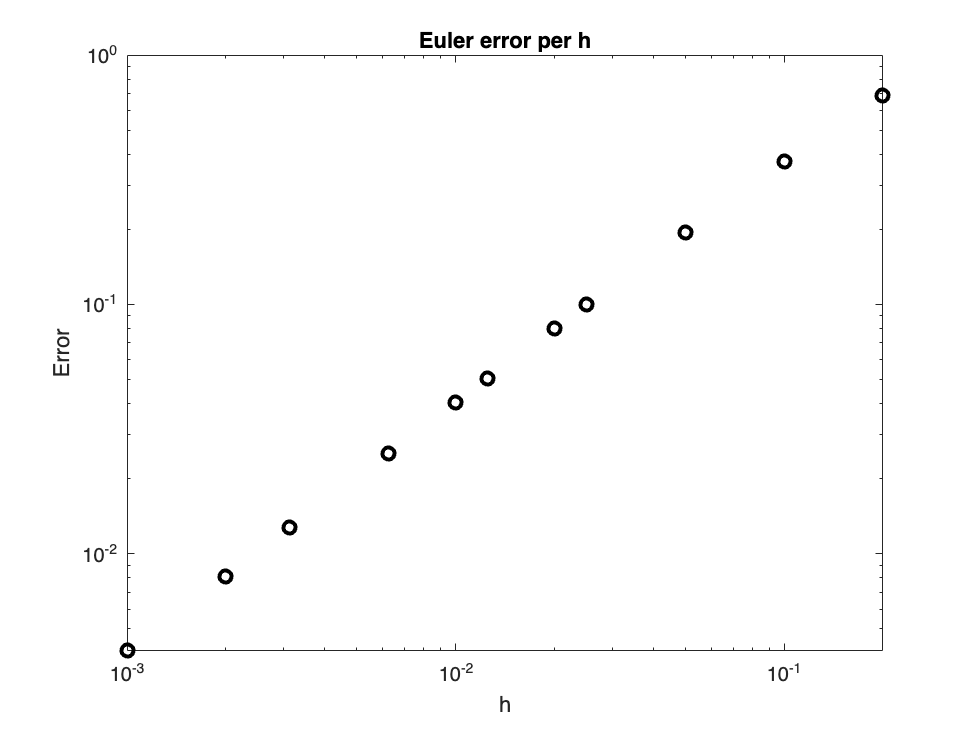


f1=figure;
loglog(hValue,error1,'o','color','black','LineWidth',2)
title('Euler error per h')
xlabel('h')
ylabel('Error')


%---- Part B - rungeKutta 2 Method ---

for i=1:hNum
    rungeKutta2Ans(1,i) = rungeKutta2(x0,y0,hValue(1,i));
end

error2= vpa(abs(rungeKutta2Ans-exact))

$$error2 = \left(\begin{array}{ccccccccccc} 0.0467209957771359 & 0.0126029455524623 & 0.00327232231248152 & 0.000833652264207164 & 0.000535549163613414 & 0.000210382079062644 & 0.000134897697263259 & 0.0000528430267738751 & 0.0000132417803584313 & 0.00000542841352845284 & 0.00000135812185319066 \end{array}\right)$$

rungeKutta2Ans= vpa(rungeKutta2Ans)

$$rungeKutta2Ans = \left(\begin{array}{ccccccccccc} 10.1081244896 & 10.1422425398247 & 10.1515731630647 & 10.1540118331129 & 10.1543099362135 & 10.1546351032981 & 10.1547105876799 & 10.1547926423504 & 10.1548322435968 & 10.1548400569636 & 10.1548441272553 \end{array}\right)$$

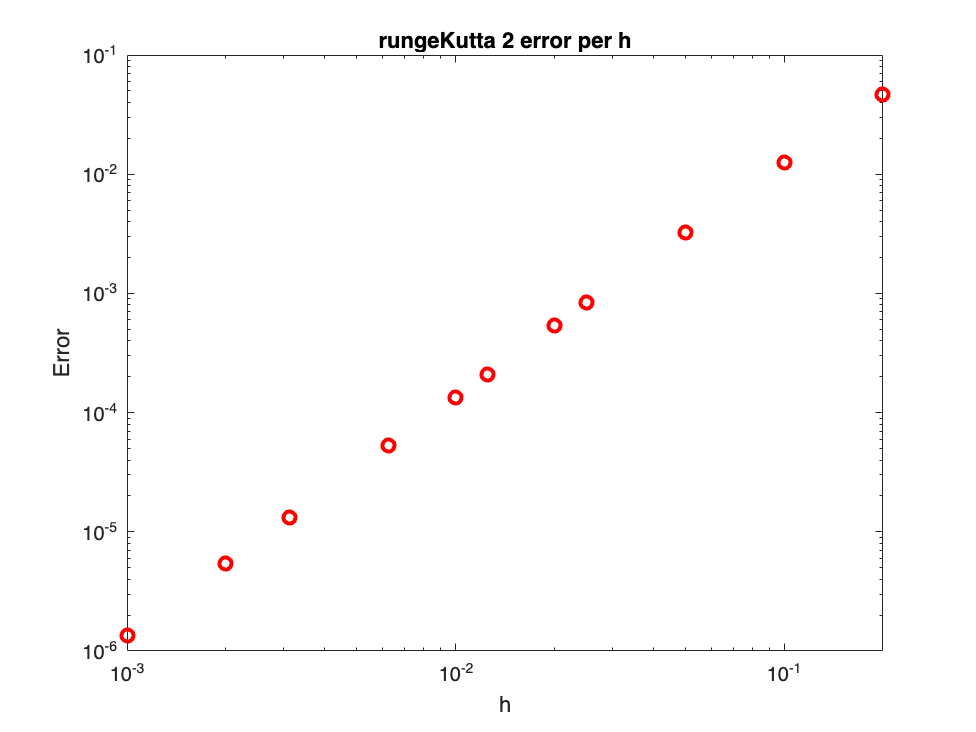


f2=figure;
loglog(hValue,error2,'o','color','red','LineWidth',2)
title('rungeKutta 2 error per h')
xlabel('h')
ylabel('Error')


%---- Part C - rungeKutta 4 Method ---

for i=1:hNum
    rungeKutta4Ans(1,i) = rungeKutta4(x0,y0,hValue(1,i));
end

error3= vpa(abs(rungeKutta4Ans-exact))

$$error3 = \left(\begin{array}{ccccccccccc} 0.0000920755593298746 & 0.00000625297163913201 & 0.00000040740813388522 & 0.0000000259985668445282 & 0.0000000106934532236167 & 0.00000000164191681432871 & 0.000000000673932010904849 & 0.0000000001031548076256 & 0.00000000000646415214336567 & 0.00000000000108534363366171 & 0.0000000000000674911646853643 \end{array}\right)$$

rungeKutta4Ans= vpa(rungeKutta4Ans)

$$rungeKutta4Ans = \left(\begin{array}{ccccccccccc} 10.1547534098178 & 10.1548392324055 & 10.154845077969 & 10.1548454593786 & 10.1548454746837 & 10.1548454837352 & 10.1548454847032 & 10.154845485274 & 10.1548454853707 & 10.1548454853761 & 10.1548454853771 \end{array}\right)$$

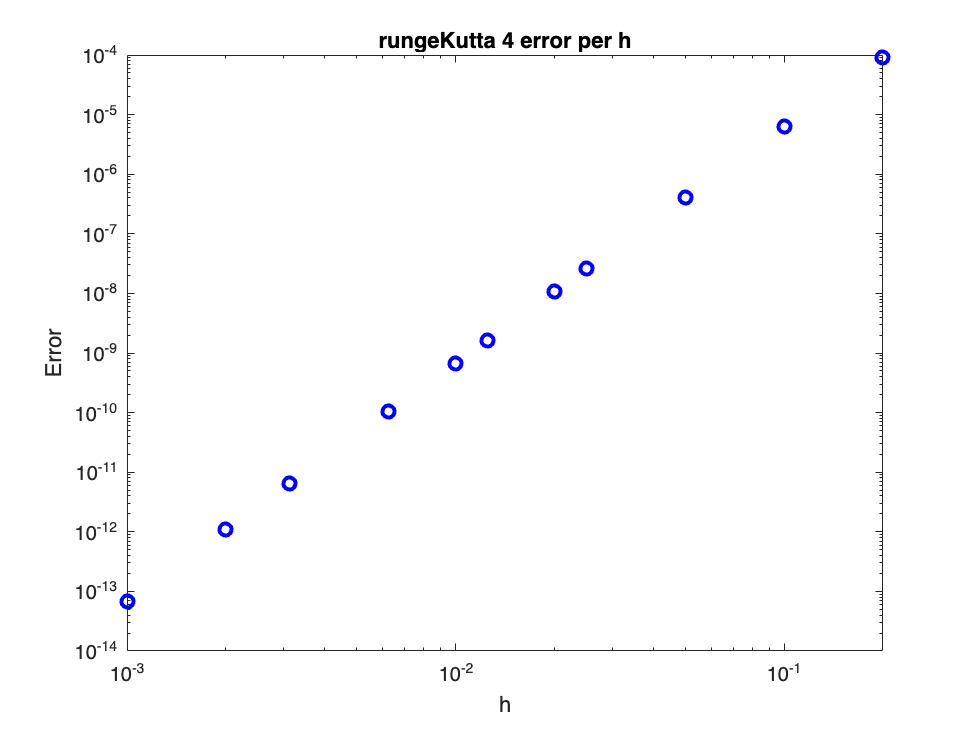


f3=figure;
loglog(hValue,error3,'o','color','blue','LineWidth',2)
title('rungeKutta 4 error per h')
xlabel('h')
ylabel('Error')

function result = euler(xn,yn,h)
    syms x y f(x,y)
    f(x,y)= y-2*x+2;

    n= 1/h ;
    
    for i= 1:n
        yn = yn + h*f(xn,yn);
        xn= xn+h;
    end

    result= yn ;
end

function result = rungeKutta2(xn,yn,h)
    syms x y f(x,y)
    f(x,y)= y-2*x+2;

    n= 1/h ;
    
    for i= 1:n
        k1=h*f(xn,yn);

        k2=h*f(xn+h, yn+k1);

        yn = yn + 0.5*(k1+k2);
        xn= xn + h;
    end

    result= yn ;
end

function result = rungeKutta4(xn,yn,h)
    syms x y f(x,y)
    f(x,y)= y-2*x+2;

    n= 1/h ;
    
    for i= 1:n

        k1=h*f(xn,yn);
        k2=h*f(xn+(h/2), yn+(k1/2));
        k3=h*f(xn+(h/2), yn+(k2/2));
        k4=h*f(xn+h, yn+k3);

        yn = yn + (1/6)*(k1+2*k2+2*k3+k4);
        xn= xn + h;
    end

    result= yn ;
end